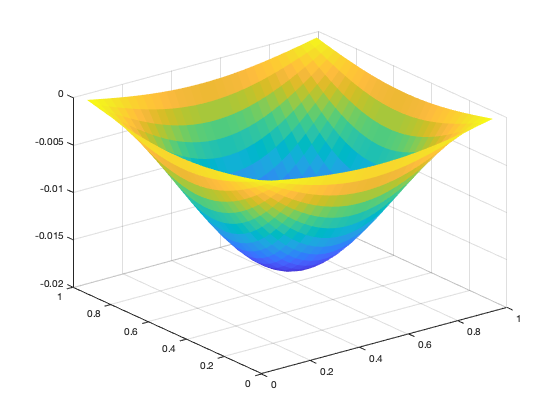

%%%%%%%%%%%%%%%%%%%Set Up%%%%%%%%%%%%%%%%%%%%%%

f = @(x,y) 2 * sin(pi*x).*sin(pi*y);
u_exact = @(x,y) -sin(pi*x).*sin(pi*y)/(pi*pi);

N = 32;
x = linspace(0,1,N)';
y = linspace(0,1,N)';
m = N - 2; 
h = x(2) - x(1);
[xx,yy] = meshgrid(x,y);

% F vector
F = f(xx(2:end-1,2:end-1),yy(2:end-1,2:end-1));
F = F(:); 

%%%%%%%%%%%%Boundary Conditions%%%%%%%%%%%%%%%%%

% Set Boundaries
F(1:m) = F(1:m) - u_exact(x(2:end-1),y(1)) / h^2;
F((end-m+1):end) = F((end-m+1):end) - u_exact(x(2:end-1),y(end)) / h^2;
F(1:m:end) = F(1:m:end) - u_exact(x(1),y(2:end-1)) / h^2;
F(m:m:end) = F(m:m:end) - u_exact(x(end),y(2:end-1)) / h^2;

%%%%%%%%%%%%%%%%Create Matrix A%%%%%%%%%%%%%%%%%

I = eye(m);
e = ones(m,1);
S = spdiags([e e], [-1 1], m, m);
T = spdiags([4*e -20*e 4*e], [-1 0 1], m, m);
R = spdiags([e 4*e e],[-1 0 1], m, m);
A = (kron(I, T) + kron(S, R))/h^2;
UU = A\F;

exactSol = u_exact(xx(2:end-1,2:end-1),yy(2:end-1,2:end-1));
a = reshape(exactSol, m*m, 1);
E = abs(UU - a);
tao = max(A * E);

UU = reshape(UU, m, m);

%%%%%%%%%%%%%%%%%Grahping%%%%%%%%%%%%%%%%%%%%%%%

[x_draw, y_draw] = meshgrid(x(2:end-1), y(2:end-1));

figure(1); clf;
fig = surf(x_draw,y_draw,UU);
set(fig,'EdgeColor','None');